% import confusionmatStats function
addpath('C:\Users\Diego\Desktop\matprojects\funciones');

stroke=readtable('C:\Users\Diego\OneDrive - Universidad Autonoma de Madrid\metodologia\TECNOLOGIA DEL CONOCIMIENTO\datos_TC\stroke2.csv');
features=stroke(:,["age_cat","hypertension","glucose_cat", ...
    "heart_disease","gender","bmi_cat"]);
group=stroke{:,"stroke"};

Ajuste modelo base con todos los predictores y sin matriz de costes

rng(13)
allfeatures=stroke(:,["age_cat","hypertension","glucose_cat", ...
    "heart_disease","gender","bmi_cat"]);
% split in train and test set
part=cvpartition(group,'HoldOut',.3, 'Stratify',true); % stratify to make sure same priors
ids_train=training(part);
ids_test=test(part);

% Split criterion based on information gain, no cost for false negatives
treebase=fitctree(allfeatures(ids_train,:),group(ids_train,:), ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance');

[predsbase, postprobsbase]=predict(treebase,features(ids_test,:));
% model...........
view(treebase)

Decision tree for classification
1  class = No


treebase.ModelParameters

ans =         SplitCriterion: 'deviance'
             MinParent: 10
               MinLeaf: 1
             MaxSplits: 30379
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 2
                Method: 'Tree'
                  Type: 'classification'

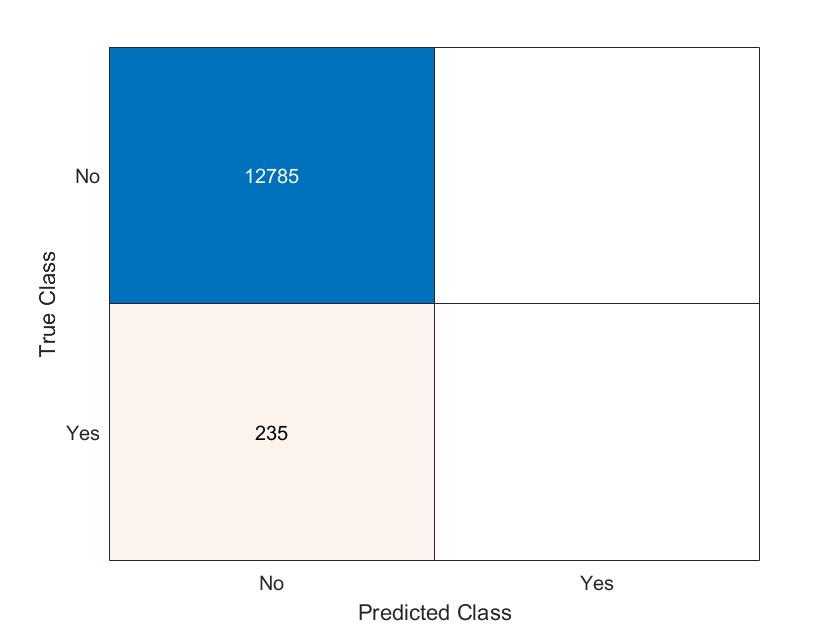

% assessment...........
confusionchart(group(ids_test,:),predsbase);

c=confusionmatStats(group(ids_test,:),predsbase);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore 
                 ________    ___________    ___________    _______
    Class No     0.98195          1              0         0.99089
    Class Yes    0.98195          0              1               0

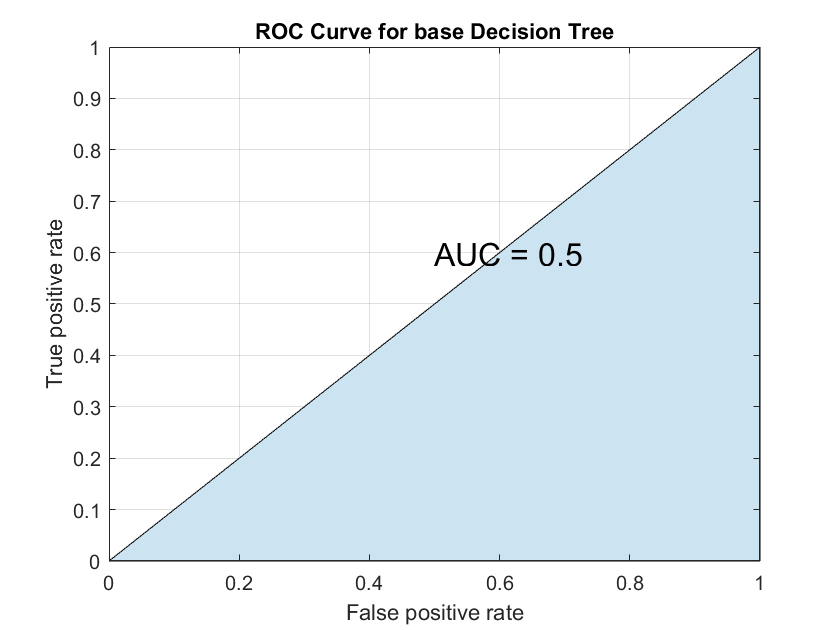


% ROC...........
[FPRbase, TPRbase, ~, AUCbase]=perfcurve(group(ids_test),postprobsbase(:,2),'Yes');
area(FPRbase,TPRbase,'FaceColor',[0.8 0.89 0.95]);
grid on
% plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
text(.5,.6,['AUC = ' num2str(AUCbase)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for base Decision Tree')

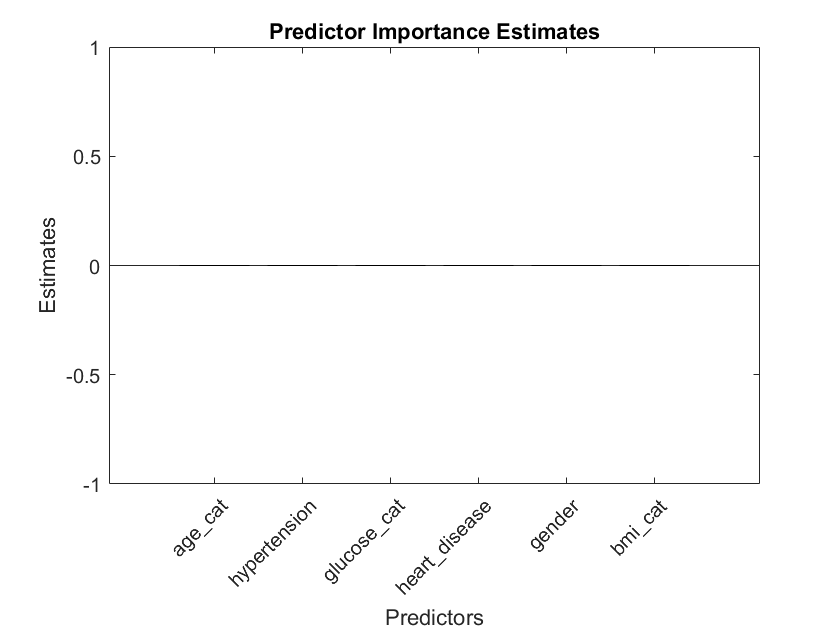


% important features
imp=predictorImportance(treebase);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = treebase.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

Modelo 1 con todos los predictores pero con matriz de costes [0 10;100 0]

allfeatures=stroke(:,["age_cat","hypertension","glucose_cat", ...
    "heart_disease","gender","bmi_cat"]);

% Split criterion based on information gain, high cost of false negatives
tree=fitctree(allfeatures(ids_train,:),group(ids_train,:), ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'Cost',[0 10;100 0]);

[preds, postprobs]=predict(tree,features(ids_test,:));
% model...........
view(tree)

Decision tree for classification
  1  if age_cat=Elder then node 2 elseif age_cat in {Kid Mature Young} then node 3 else No
  2  if bmi_cat=NA then node 4 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 5 else No
  3  if age_cat in {Kid Young} then node 6 elseif age_cat=Mature then node 7 else No
  4  if hypertension=No then node 8 elseif hypertension=Yes then node 9 else Yes
  5  if glucose_cat=Diabetes then node 10 elseif glucose_cat in {Normal Pre-diabetes} then node 11 else No
  6  class = No
  7  if bmi_cat=NA then node 12 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 13 else No
  8  if heart_disease=No then node 14 elseif heart_disease=Yes then node 15 else Yes
  9  if heart_disease=No then node 16 elseif heart_disease=Yes then node 17 else Yes
 10  if heart_disease=No then node 18 elseif heart_disease=Yes then node 19 else No
 11  if hypertension=No then node 20 elseif hypertension=Yes then node 21 else No
 12  if hypertension=No then node 2

tree.ModelParameters

ans =         SplitCriterion: 'deviance'
             MinParent: 10
               MinLeaf: 1
             MaxSplits: 30379
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 2
                Method: 'Tree'
                  Type: 'classification'

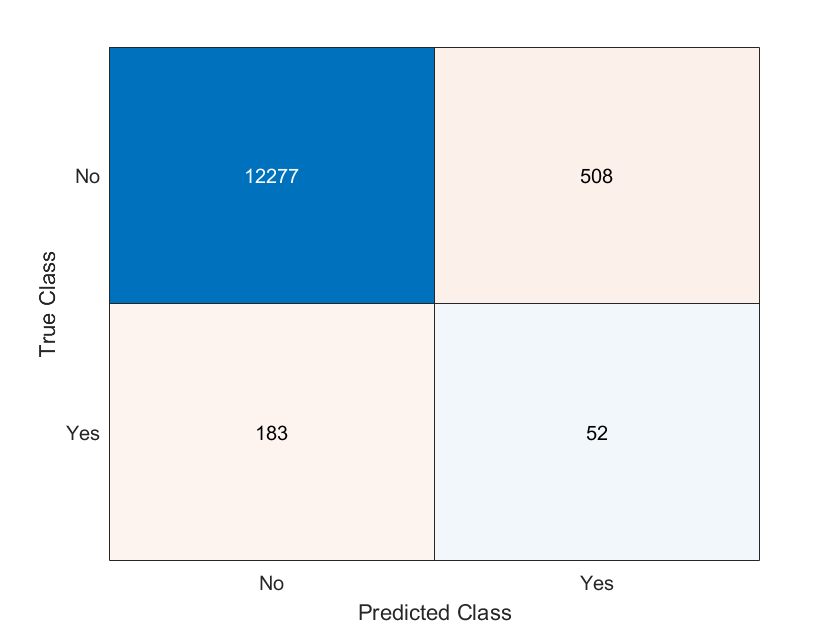

% assessment...........
confusionchart(group(ids_test,:),preds);

c=confusionmatStats(group(ids_test,:),preds);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore 
                 ________    ___________    ___________    _______
    Class No     0.94693       0.96027        0.22128      0.97263
    Class Yes    0.94693       0.22128        0.96027      0.13082

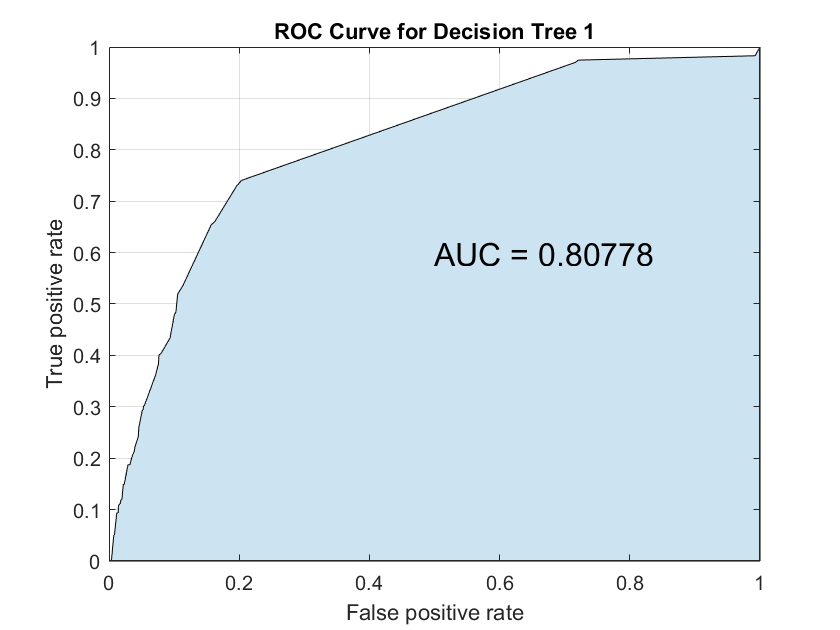


% ROC...........
[FPR, TPR, ~, AUC]=perfcurve(group(ids_test),postprobs(:,2),'Yes');
area(FPR,TPR,'FaceColor',[0.8 0.89 0.95]);
grid on
% plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
text(.5,.6,['AUC = ' num2str(AUC)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for Decision Tree 1')

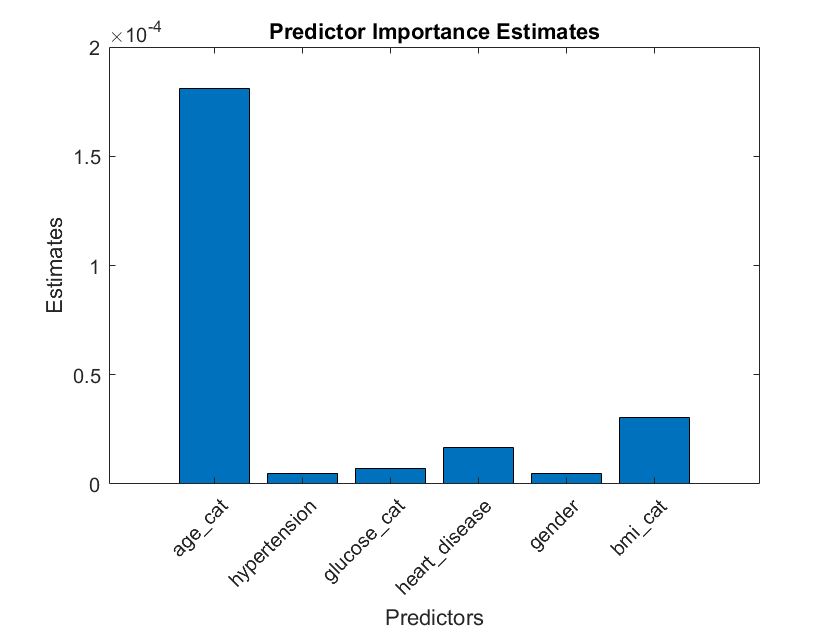


% important features
imp=predictorImportance(tree);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = tree.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

Modelo 2 con todos los predictores salvo *gender_cat*  pero con matriz de costes [0 1;70 0]

features2=stroke(:,["age_cat","hypertension","glucose_cat", ...
    "heart_disease","bmi_cat"]); % no gender
tree2=fitctree(features2(ids_train,:),group(ids_train,:), ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'Cost',[0 1;70 0]); % different cost matrix
% predictions
[preds2, postprobs2]=predict(tree2,features2(ids_test,:));

% model...........
view(tree2)

Decision tree for classification
 1  if age_cat=Elder then node 2 elseif age_cat in {Kid Mature Young} then node 3 else Yes
 2  if bmi_cat=NA then node 4 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 5 else Yes
 3  if age_cat in {Kid Young} then node 6 elseif age_cat=Mature then node 7 else No
 4  class = Yes
 5  if glucose_cat=Diabetes then node 8 elseif glucose_cat in {Normal Pre-diabetes} then node 9 else Yes
 6  if bmi_cat=NA then node 10 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 11 else No
 7  if bmi_cat=NA then node 12 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 13 else No
 8  if heart_disease=No then node 14 elseif heart_disease=Yes then node 15 else Yes
 9  if hypertension=No then node 16 elseif hypertension=Yes then node 17 else Yes
10  if age_cat=Kid then node 18 elseif age_cat=Young then node 19 else No
11  class = No
12  if hypertension=No then node 20 elseif hypertension=Yes then node 21 else Yes
13  if hear

tree2.ModelParameters

ans =         SplitCriterion: 'deviance'
             MinParent: 10
               MinLeaf: 1
             MaxSplits: 30379
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 2
                Method: 'Tree'
                  Type: 'classification'

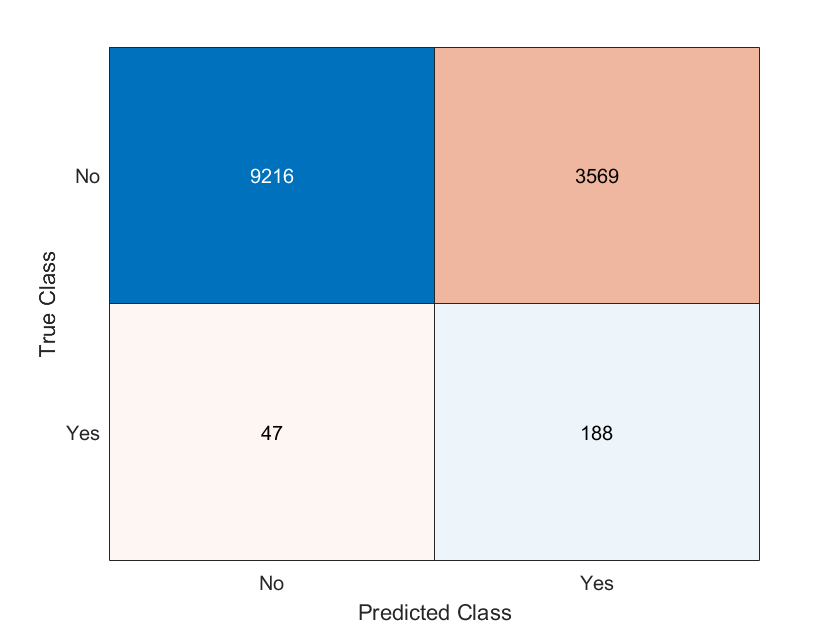


% assessment...........
confusionchart(group(ids_test,:),preds2);

c=confusionmatStats(group(ids_test,:),preds2);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________
    Class No     0.72227       0.72084            0.8       0.83599
    Class Yes    0.72227           0.8        0.72084      0.094188

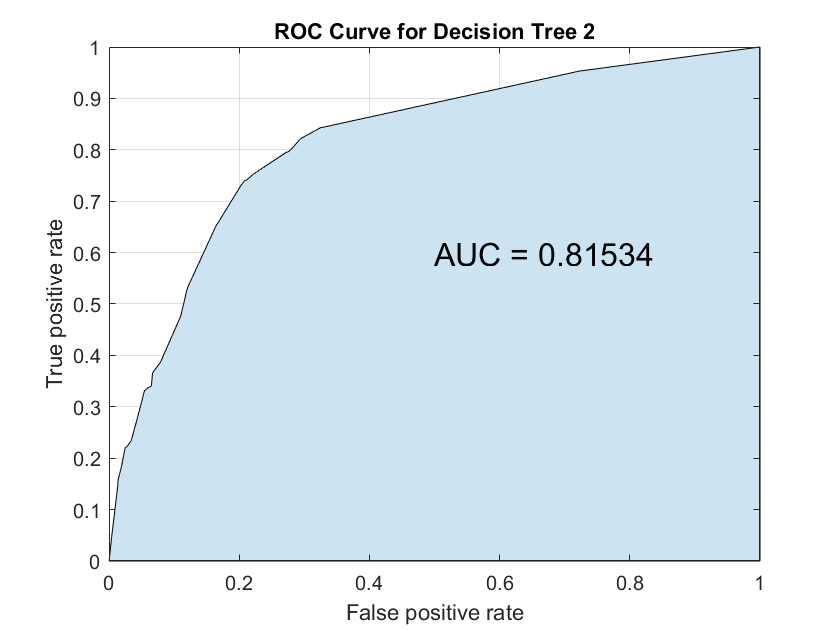


% ROC...........
[FPR2, TPR2, ~, AUC2]=perfcurve(group(ids_test),postprobs2(:,2),'Yes');
area(FPR2,TPR2,'FaceColor',[0.8 0.89 0.95]);
hold on
% plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
grid on
text(.5,.6,['AUC = ' num2str(AUC2)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for Decision Tree 2')
hold off

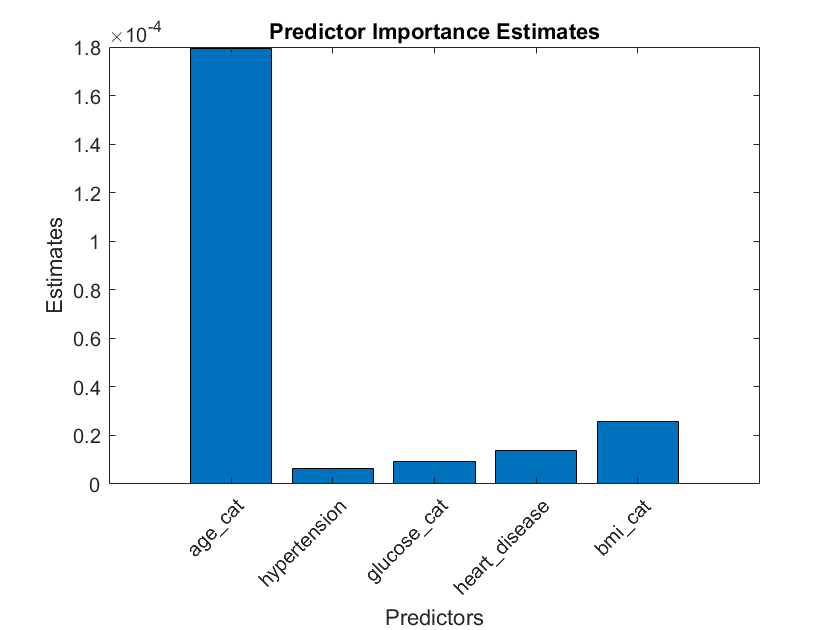


% important features
imp=predictorImportance(tree2);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = tree2.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

 Modelo 3 con todos los predictores salvo *gender_cat* y *glucose_cat*  pero con matriz de costes [0 1;70 0]

features3=stroke(:,["age_cat","hypertension", ...
    "heart_disease","bmi_cat"]); % no gender, no glucose_cat
tree3=fitctree(features3(ids_train,:),group(ids_train,:), ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'Cost',[0 1;70 0]); 
% predictions
[preds3, postprobs3]=predict(tree3,features3(ids_test,:));

% model...........
view(tree3)

Decision tree for classification
 1  if age_cat=Elder then node 2 elseif age_cat in {Kid Mature Young} then node 3 else Yes
 2  if bmi_cat=NA then node 4 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 5 else Yes
 3  if age_cat in {Kid Young} then node 6 elseif age_cat=Mature then node 7 else No
 4  class = Yes
 5  if heart_disease=No then node 8 elseif heart_disease=Yes then node 9 else Yes
 6  if bmi_cat=NA then node 10 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 11 else No
 7  if bmi_cat=NA then node 12 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 13 else No
 8  if hypertension=No then node 14 elseif hypertension=Yes then node 15 else Yes
 9  class = Yes
10  if age_cat=Kid then node 16 elseif age_cat=Young then node 17 else No
11  class = No
12  if hypertension=No then node 18 elseif hypertension=Yes then node 19 else Yes
13  if heart_disease=No then node 20 elseif heart_disease=Yes then node 21 else No
14  if bmi_cat in {

tree3.ModelParameters

ans =         SplitCriterion: 'deviance'
             MinParent: 10
               MinLeaf: 1
             MaxSplits: 30379
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 2
                Method: 'Tree'
                  Type: 'classification'

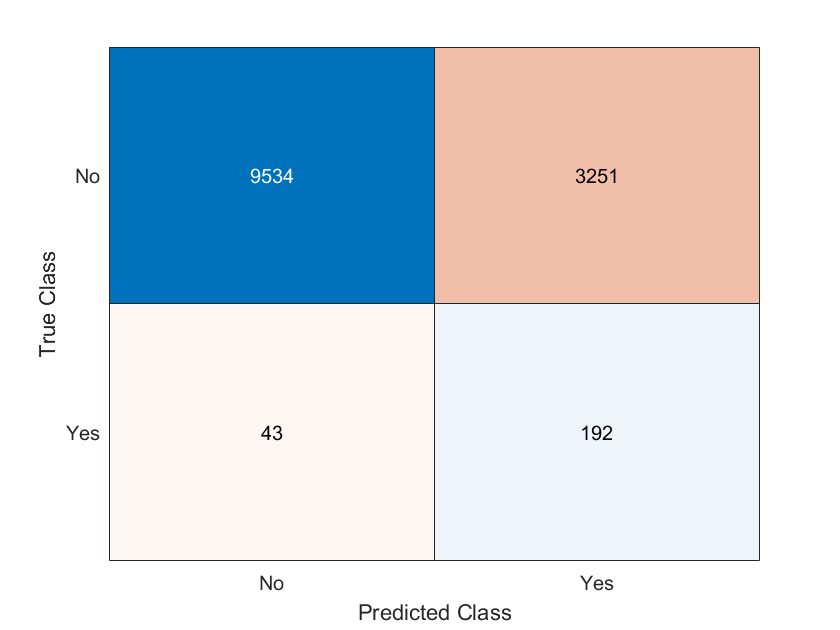


% assessment...........
confusionchart(group(ids_test,:),preds3);

c=confusionmatStats(group(ids_test,:),preds3);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore
                 ________    ___________    ___________    ______
    Class No      0.747        0.74572        0.81702      0.8527
    Class Yes     0.747        0.81702        0.74572      0.1044

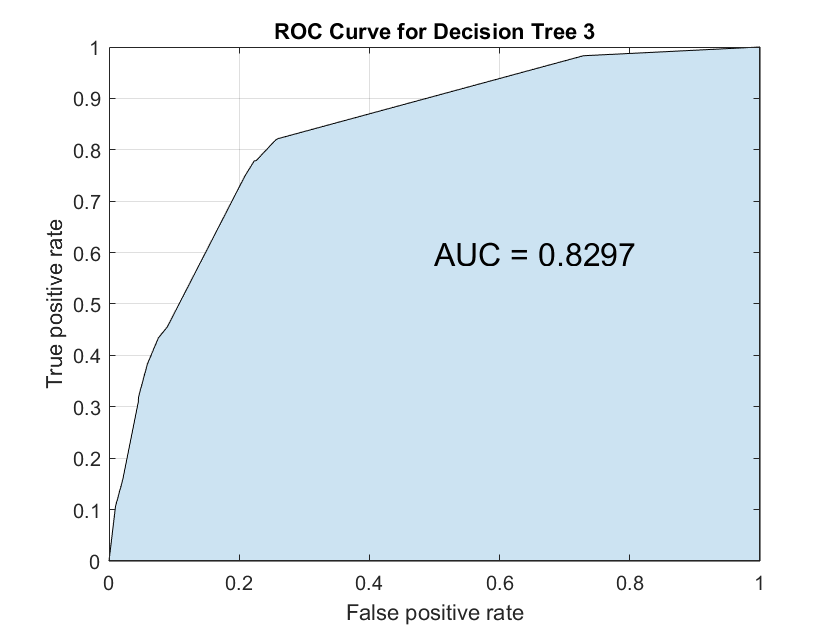


% ROC...........
[FPR3, TPR3, ~, AUC3]=perfcurve(group(ids_test),postprobs3(:,2),'Yes');
area(FPR3,TPR3,'FaceColor',[0.8 0.89 0.95]);
hold on
% plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
grid on
text(.5,.6,['AUC = ' num2str(AUC3)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for Decision Tree 3')
hold off

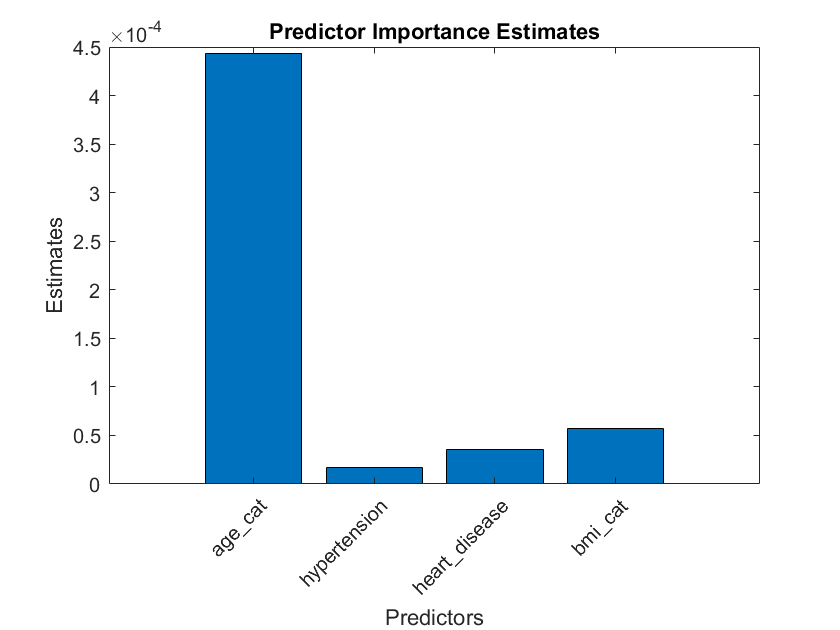


% important features
imp=predictorImportance(tree3);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = tree3.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

Modelo con todos los predictores salvo *age_cat* y matriz de costes [0 1;70 0]

featuresnoage=stroke(:,["hypertension","glucose_cat", ...
    "heart_disease","gender","bmi_cat"]);

tree4=fitctree(featuresnoage(ids_train,:),group(ids_train,:), ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'Cost',[0 1;70 0]); 
% predictions
[preds4, postprobs4]=predict(tree4,featuresnoage(ids_test,:));

% model...........
view(tree4)

Decision tree for classification
  1  if heart_disease=No then node 2 elseif heart_disease=Yes then node 3 else Yes
  2  if bmi_cat=NA then node 4 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 5 else Yes
  3  if glucose_cat=Diabetes then node 6 elseif glucose_cat in {Normal Pre-diabetes} then node 7 else Yes
  4  if hypertension=No then node 8 elseif hypertension=Yes then node 9 else Yes
  5  if hypertension=No then node 10 elseif hypertension=Yes then node 11 else No
  6  if bmi_cat=Obese then node 12 elseif bmi_cat in {NA Normal Overweight Underweight} then node 13 else Yes
  7  if hypertension=No then node 14 elseif hypertension=Yes then node 15 else Yes
  8  if gender in {Female Male} then node 16 elseif gender=Other then node 17 else Yes
  9  if glucose_cat=Diabetes then node 18 elseif glucose_cat in {Normal Pre-diabetes} then node 19 else Yes
 10  if glucose_cat=Diabetes then node 20 elseif glucose_cat in {Normal Pre-diabetes} then node 21 else No
 11  if bmi_

tree4.ModelParameters

ans =         SplitCriterion: 'deviance'
             MinParent: 10
               MinLeaf: 1
             MaxSplits: 30379
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 2
                Method: 'Tree'
                  Type: 'classification'

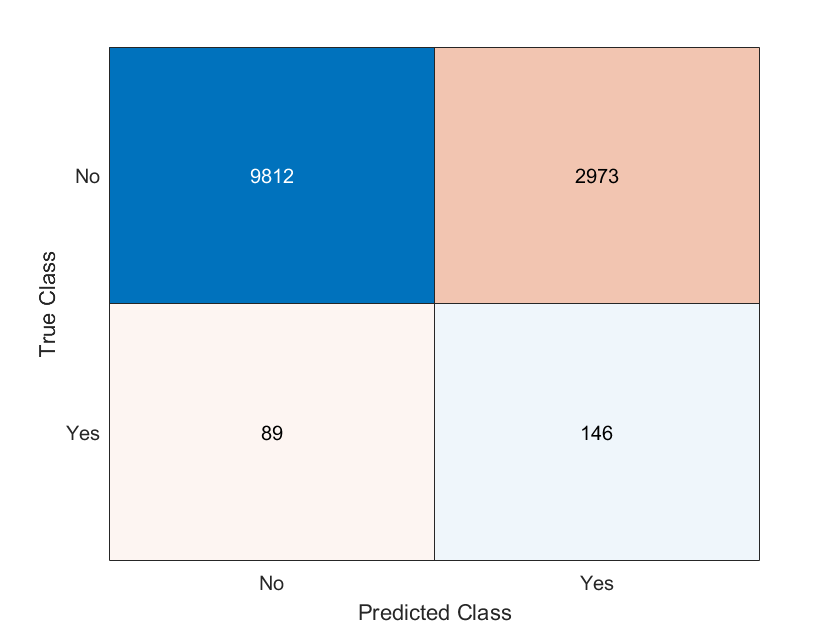


% assessment...........
confusionchart(group(ids_test,:),preds4);

c=confusionmatStats(group(ids_test,:),preds4);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore 
                 ________    ___________    ___________    _______
    Class No     0.76482       0.76746        0.62128      0.86503
    Class Yes    0.76482       0.62128        0.76746      0.08706

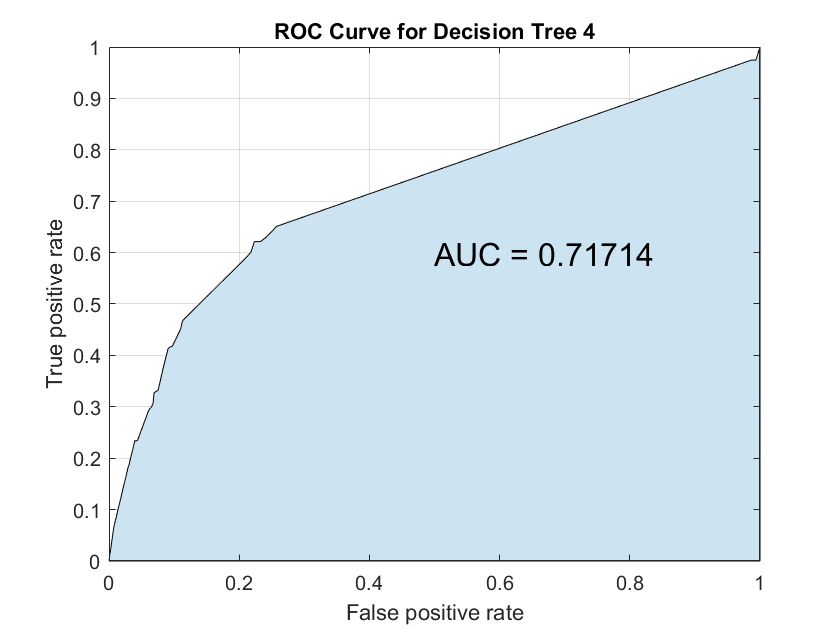


% ROC...........
[FPR4, TPR4, ~, AUC4]=perfcurve(group(ids_test),postprobs4(:,2),'Yes');
area(FPR4,TPR4,'FaceColor',[0.8 0.89 0.95]);
hold on
% plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
grid on
text(.5,.6,['AUC = ' num2str(AUC4)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for Decision Tree 4')
hold off

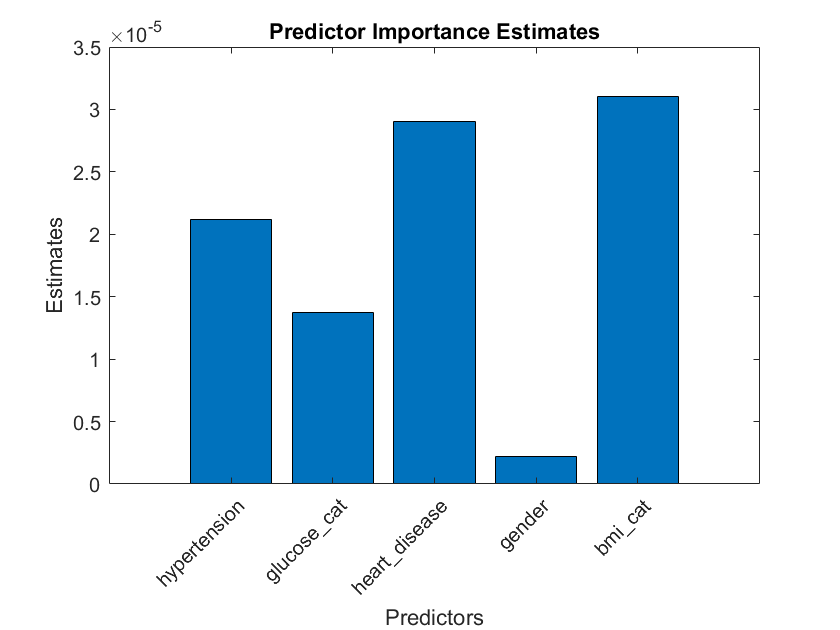


% important features
imp=predictorImportance(tree4);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = tree4.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

Comparación curvas ROC

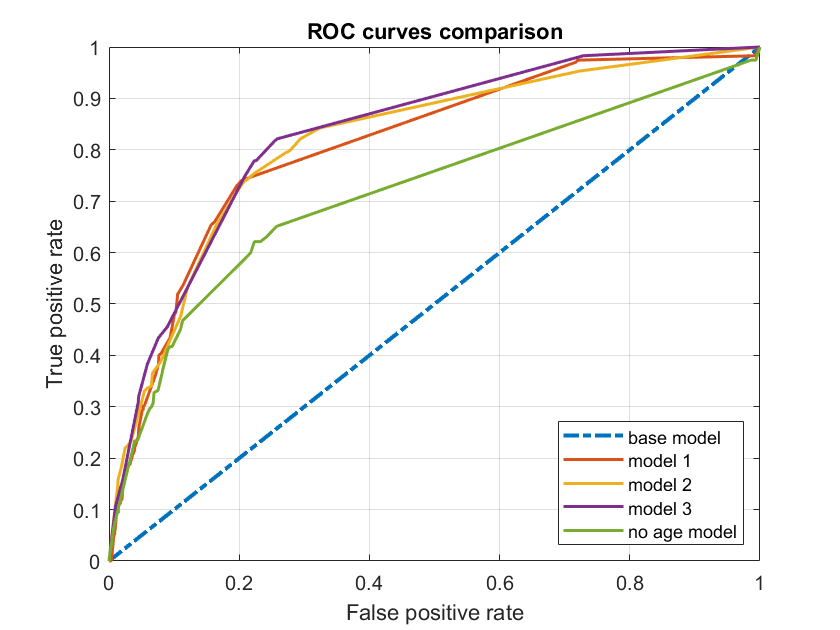

plot(FPRbase,TPRbase,'LineWidth',2,'LineStyle',"-.");
hold on
grid on
plot(FPR,TPR,'LineWidth',1.5);
plot(FPR2,TPR2,'LineWidth',1.5);
plot(FPR3,TPR3,'LineWidth',1.5); 
plot(FPR4,TPR4,'LineWidth',1.5);
title('ROC curves comparison');
xlabel('False positive rate');
ylabel('True positive rate'); 
legend({'base model' 'model 1' 'model 2' 'model 3' 'no age model'},'Location','southeast');
hold off

Modelo 3 optimizado

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | ToSample     |
|===================================================================================================================================|
|    1 | Best   |     0.59296 |      1.3901 |     0.59296 |     0.59296 |         2323 |         1280 |     deviance |            4 |


|    2 | Best   |     0.57577 |     0.32376 |     0.57577 |     0.57689 |          678 |            1 |     deviance |            4 |


|    3 | Best   |     0.48496 |     0.32023 |     0.48496 |     0.48497 |            2 |        18072 |     deviance |            4 |


|    4 | Best   |     0.48315 |     0.29471 |     0.48315 |     0.48315 |            2 |           13 |          gdi |            4 |


|    5 | Accept |     0.58147 |     0.39239 |     0.48315 |     0.48315 |          552 |            9 |          gdi |            4 |


|    6 | Best   |     0.47544 |      0.3089 |     0.47544 |     0.47545 |            1 |           17 |          gdi |            4 |


|    7 | Accept |     0.48496 |     0.27986 |     0.47544 |     0.47545 |            1 |        23853 |     deviance |            4 |


|    8 | Accept |     0.52337 |     0.22743 |     0.47544 |     0.47545 |            1 |            7 |          gdi |            4 |


|    9 | Accept |     0.48058 |     0.23914 |     0.47544 |     0.47545 |            3 |           25 |          gdi |            4 |


|   10 | Accept |     0.48525 |     0.26184 |     0.47544 |     0.47544 |            8 |        30361 |     deviance |            4 |


|   11 | Accept |     0.48496 |     0.41639 |     0.47544 |     0.47544 |            1 |           60 |          gdi |            4 |


|   12 | Accept |     0.48058 |     0.36367 |     0.47544 |     0.47546 |            1 |           27 |          gdi |            4 |


|   13 | Accept |     0.48137 |     0.37523 |     0.47544 |     0.47545 |           19 |          174 |          gdi |            4 |


|   14 | Accept |     0.48496 |      0.2599 |     0.47544 |     0.47545 |            1 |          290 |          gdi |            4 |


|   15 | Accept |     0.48144 |     0.28219 |     0.47544 |     0.47545 |           70 |          696 |          gdi |            4 |


|   16 | Accept |     0.48496 |      0.2878 |     0.47544 |     0.47545 |            1 |         1488 |          gdi |            4 |


|   17 | Accept |     0.48097 |     0.24204 |     0.47544 |     0.47545 |          210 |         2697 |          gdi |            4 |


|   18 | Accept |     0.48506 |     0.29217 |     0.47544 |     0.47545 |            4 |         7423 |          gdi |            4 |


|   19 | Accept |     0.59296 |     0.21561 |     0.47544 |     0.48255 |         3837 |        10552 |          gdi |            4 |


|   20 | Accept |     0.48219 |     0.26354 |     0.47544 |     0.48239 |           47 |        12733 |          gdi |            4 |


|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | ToSample     |
|===================================================================================================================================|
|   21 | Accept |     0.48506 |     0.25595 |     0.47544 |     0.47945 |            6 |          545 |          gdi |            4 |


|   22 | Accept |     0.48239 |     0.28222 |     0.47544 |     0.47903 |           44 |         3813 |          gdi |            4 |


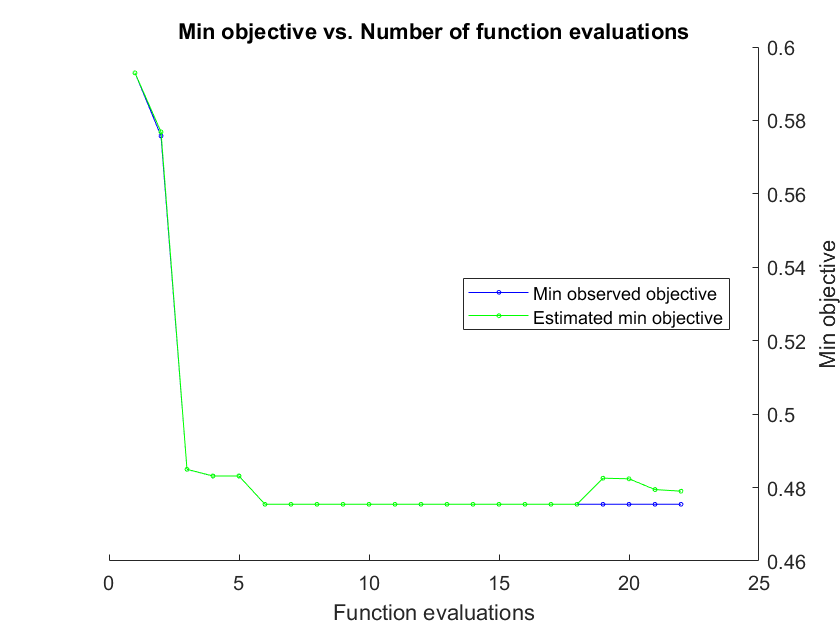

|   23 | Accept |     0.48496 |     0.68955 |     0.48232 |     0.48226 |            1 |         5061 |          gdi |            4 |


|   24 | Best   |     0.48144 |     0.59377 |     0.48144 |     0.48144 |           56 |        29562 |          gdi |            4 |


|   25 | Accept |     0.59296 |     0.53467 |     0.48144 |     0.48145 |         3462 |        30106 |          gdi |            4 |


|   26 | Accept |     0.48479 |     0.62352 |     0.48144 |     0.48146 |           11 |        29918 |          gdi |            4 |


|   27 | Accept |     0.48496 |     0.61884 |     0.48144 |     0.48146 |            1 |         1665 |     deviance |            4 |


|   28 | Best   |     0.48058 |     0.66231 |     0.48058 |     0.48056 |            5 |           31 |          gdi |            4 |


|   29 | Accept |     0.48137 |     0.58956 |     0.48058 |     0.48056 |           39 |         8005 |          gdi |            4 |


|   30 | Accept |     0.48496 |     0.71698 |     0.48058 |     0.48055 |            2 |         4959 |     deviance |            4 |


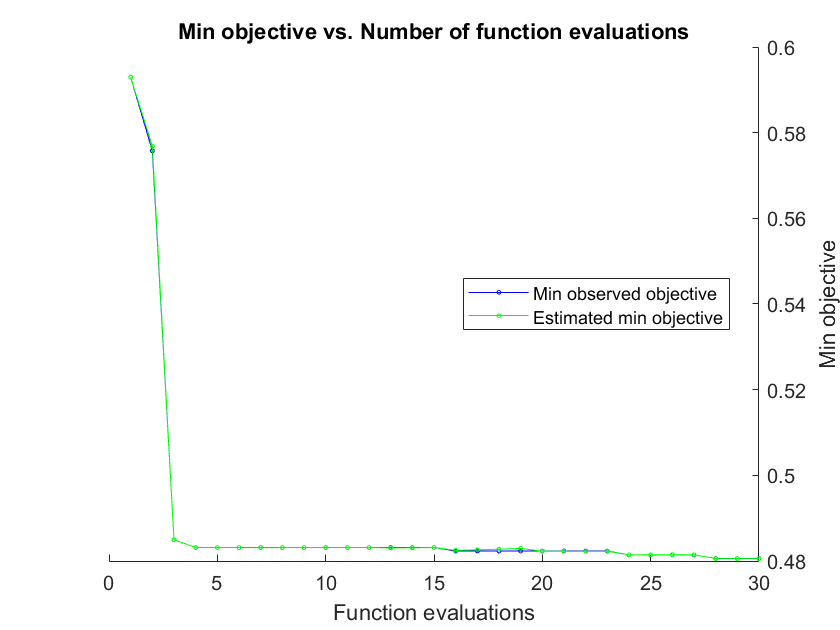


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 99.5737 seconds
Total objective function evaluation time: 19.9984

Best observed feasible point:
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    ____________    ______________    ____________________
         5              31              gdi                   4          
Observed objective function value = 0.48058
Estimated objective function value = 0.48055
Function evaluation time = 0.66231

Best estimated feasible point (according to models):
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    _______

features3=stroke(:,["age_cat","hypertension", ...
    "heart_disease","bmi_cat"]); % no gender, no glucose_cat
treeopt=fitctree(features3(ids_train,:),group(ids_train,:), ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'OptimizeHyperparameters','all', ... % automatically optimize hyperparameters
    'Cost',[0 1;70 0]); 

% predictions
[predsopt, postprobsopt]=predict(treeopt,features3(ids_test,:));

% model...........
view(treeopt)

Decision tree for classification
 1  if age_cat=Elder then node 2 elseif age_cat in {Kid Mature Young} then node 3 else Yes
 2  if bmi_cat=NA then node 4 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 5 else Yes
 3  if age_cat in {Kid Young} then node 6 elseif age_cat=Mature then node 7 else No
 4  class = Yes
 5  if heart_disease=No then node 8 elseif heart_disease=Yes then node 9 else Yes
 6  if bmi_cat=NA then node 10 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 11 else No
 7  if bmi_cat=NA then node 12 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 13 else No
 8  if hypertension=No then node 14 elseif hypertension=Yes then node 15 else Yes
 9  class = Yes
10  if age_cat=Kid then node 16 elseif age_cat=Young then node 17 else No
11  class = No
12  if hypertension=No then node 18 elseif hypertension=Yes then node 19 else Yes
13  if heart_disease=No then node 20 elseif heart_disease=Yes then node 21 else No
14  class = Yes
15 

treeopt.ModelParameters

ans =         SplitCriterion: 'gdi'
             MinParent: 10
               MinLeaf: 5
             MaxSplits: 31
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 2
                Method: 'Tree'
                  Type: 'classification'

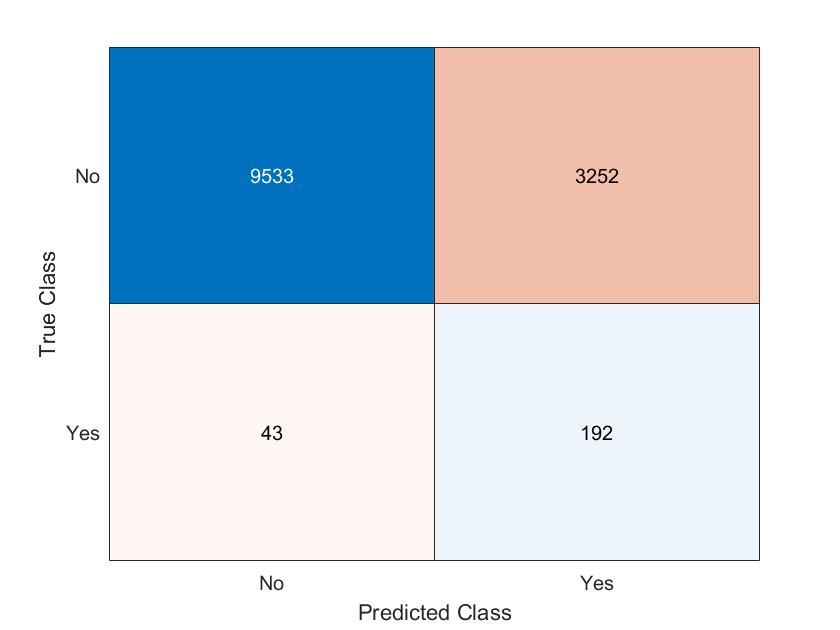


% assessment...........
confusionchart(group(ids_test,:),predsopt);

c=confusionmatStats(group(ids_test,:),predsopt);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore 
                 ________    ___________    ___________    _______
    Class No     0.74693       0.74564        0.81702      0.85265
    Class Yes    0.74693       0.81702        0.74564      0.10438

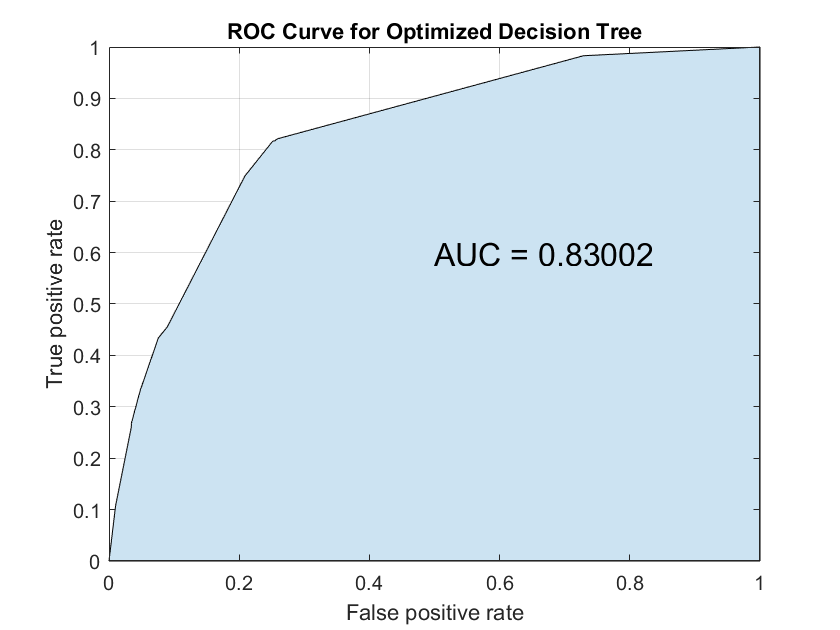


% ROC...........
[FPRopt, TPRopt, ~, AUCopt]=perfcurve(group(ids_test),postprobsopt(:,2),'Yes');
area(FPRopt,TPRopt,'FaceColor',[0.8 0.89 0.95]);
hold on
% plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
grid on
text(.5,.6,['AUC = ' num2str(AUCopt)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for Optimized Decision Tree')
hold off

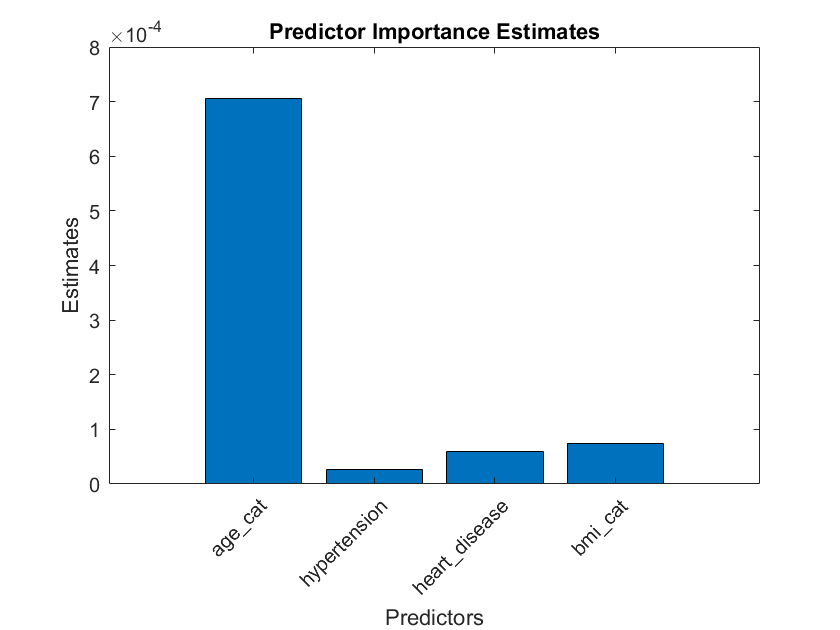


% important features
imp=predictorImportance(treeopt);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = treeopt.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

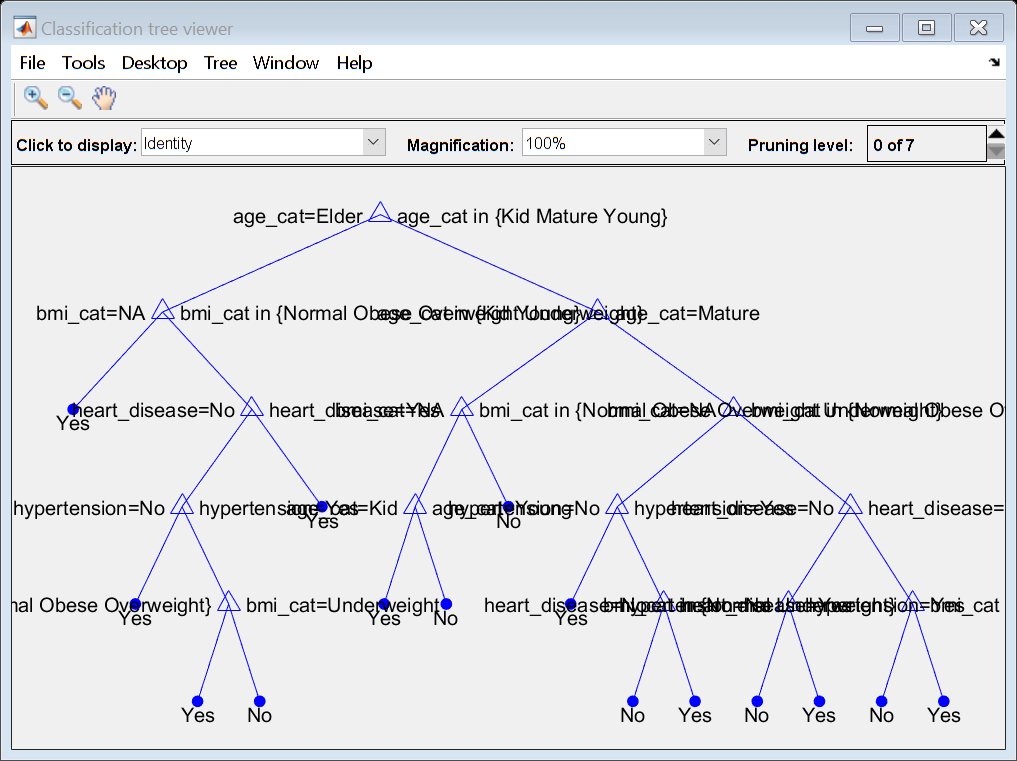

view(treeopt,'Mode','graph') % still a bit complex

Parámetros del árbol revela que aun resulta algo complejo (demasiada profundidad). Se puede comprobar que podría aumentarse el número mínimo de casos por hoja

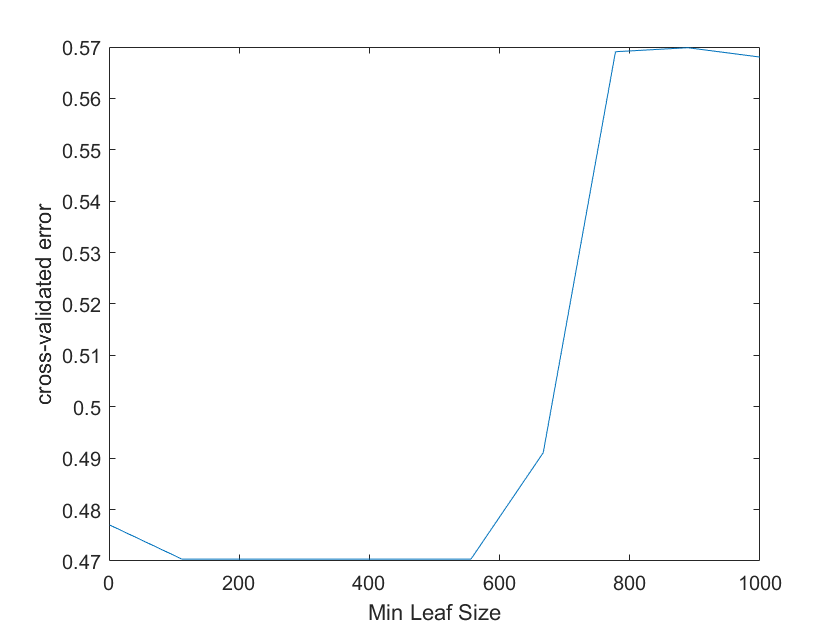

% how to find best min leaf size
leafs = logspace(1,2,10);
leafs=linspace(1,1000,10);
rng(13)
N = numel(leafs);
err = zeros(N,1);
for n=1:N
    t = fitctree(features3,group, ...
        'CategoricalPredictors','all', ...
        'SplitCriterion','deviance', ... 
        'CrossVal','On', ...
        'MinLeafSize',leafs(n), ...
        'Cost',[0 1;70 0]);
    err(n) = kfoldLoss(t);
end
plot(leafs,err,'LineWidth',1.5);
xlabel('Min Leaf Size');
ylabel('cross-validated error');

Teniendo en cuenta lo anterior se ajusta modelo con parámetros resultado de la optimización pero con MinLeafSize = 250

features3=stroke(:,["age_cat","hypertension", ...
    "heart_disease","bmi_cat"]); % no gender, no glucose_cat
treeopt=fitctree(features3(ids_train,:),group(ids_train,:), ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'MinLeafSize',250, 'MinParentSize',230, ...
    'Cost',[0 1;70 0]); 
% predictions
[predsopt, postprobsopt]=predict(treeopt,features3(ids_test,:));

% model...........
view(treeopt)

Decision tree for classification
 1  if age_cat=Elder then node 2 elseif age_cat in {Kid Mature Young} then node 3 else Yes
 2  class = Yes
 3  if age_cat in {Kid Young} then node 4 elseif age_cat=Mature then node 5 else No
 4  class = No
 5  if bmi_cat=NA then node 6 elseif bmi_cat in {Normal Obese Overweight Underweight} then node 7 else No
 6  class = Yes
 7  if heart_disease=No then node 8 elseif heart_disease=Yes then node 9 else No
 8  if hypertension=No then node 10 elseif hypertension=Yes then node 11 else No
 9  class = Yes
10  class = No
11  class = Yes


treeopt.ModelParameters

ans =         SplitCriterion: 'deviance'
             MinParent: 500
               MinLeaf: 250
             MaxSplits: 30379
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 2
                Method: 'Tree'
                  Type: 'classification'

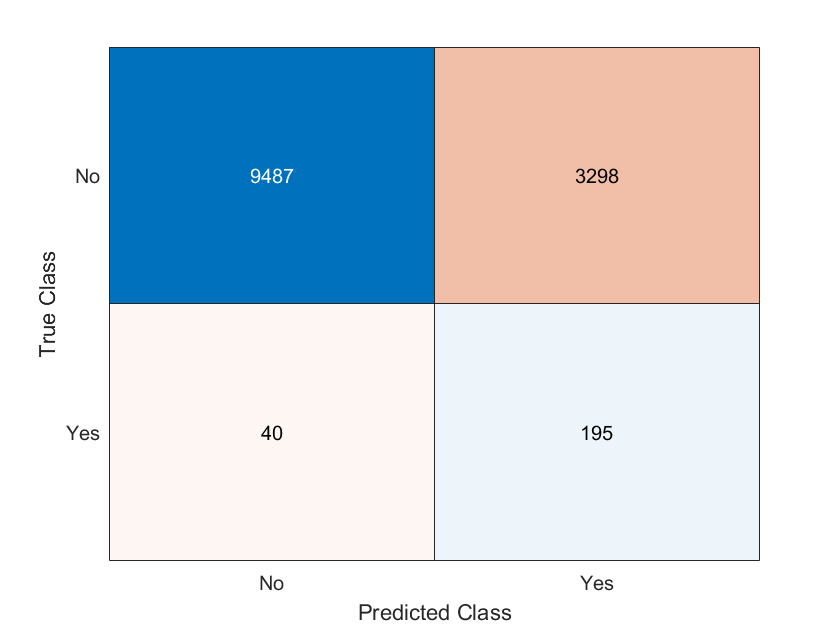


% assessment...........
confusionchart(group(ids_test,:),predsopt);

c=confusionmatStats(group(ids_test,:),predsopt);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore 
                 ________    ___________    ___________    _______
    Class No     0.74363       0.74204        0.82979      0.85039
    Class Yes    0.74363       0.82979        0.74204      0.10461

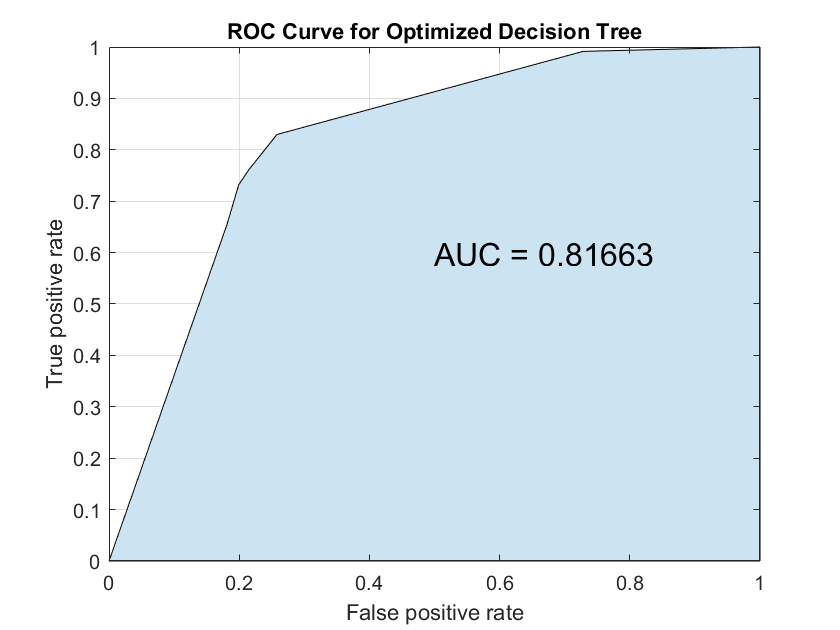


% ROC...........
[FPRopt, TPRopt, ~, AUCopt]=perfcurve(group(ids_test),postprobsopt(:,2),'Yes');
area(FPRopt,TPRopt,'FaceColor',[0.8 0.89 0.95]);
hold on
grid on
text(.5,.6,['AUC = ' num2str(AUCopt)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for Optimized Decision Tree')
hold off

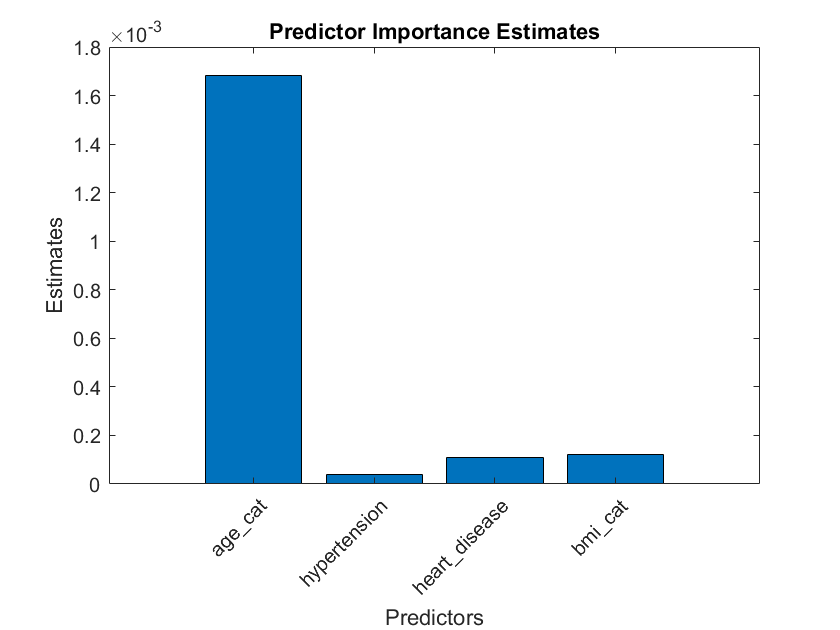


% important features
imp=predictorImportance(treeopt);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = treeopt.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

Mediante validación cruzada se evalúa este último modelo optimizado. Para calcular la importancia de cada variable, se calcula la importancia de cada una en los 10 modelos de la validación cruzada y se suman las puntuaciones.

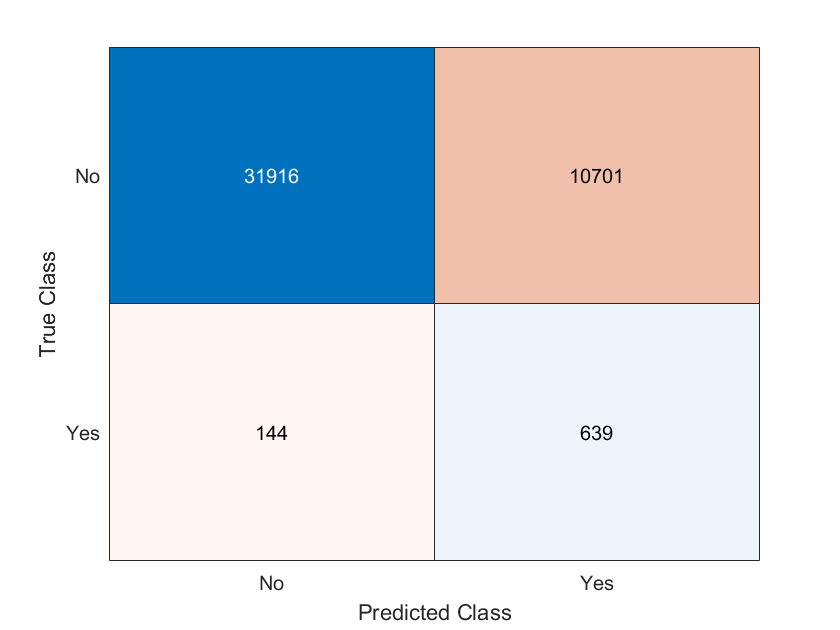

rng(13)
features3=stroke(:,["age_cat","hypertension", ...
    "heart_disease","bmi_cat"]); % no gender, no glucose_cat
treecv=fitctree(features3,group, ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'MinLeafSize',200, 'MinParentSize',230, ...
    'CrossVal','on', ... % 10-fold CV
    'Cost',[0 1;70 0]); 

[predscv,postprobcv]=kfoldPredict(treecv);
confusionchart(group,predscv);

c=confusionmatStats(group,predscv);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore 
                 ________    ___________    ___________    _______
    Class No     0.75012        0.7489        0.81609      0.85477
    Class Yes    0.75012       0.81609         0.7489      0.10542

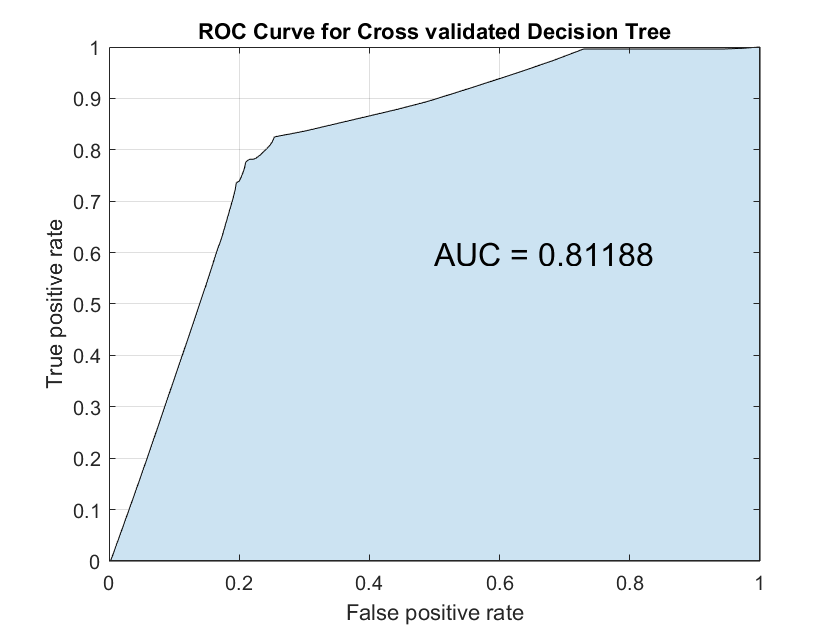


[FPRcv, TPRcv, ~, AUCcv]=perfcurve(group,postprobcv(:,2),'Yes');
area(FPRcv,TPRcv,'FaceColor',[0.8 0.89 0.95]);
hold on
% plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
grid on
text(.5,.6,['AUC = ' num2str(AUCcv)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for Cross validated Decision Tree')
hold off


% predictor importance for the 10 models generated with cross validation

sum_imp=zeros([1 4]); % there are 4 predictors
aucs=zeros([1 10]);

for i = 1:length(treecv.Trained)
    model=treecv.Trained{i};
    [~, postpr]=predict(model,features3);
    [FPRm, TPRm, ~, AUCm]=perfcurve(group,postpr(:,2),'Yes');
    aucs(i)=AUCm;
    imp=predictorImportance(model);
    sum_imp=sum_imp+imp;
end

figure;
bar(sum_imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = treecv.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';



Finalmente se realizan predicciones con el modelo optimizado en toda la muestra

% rng(13)
% features3=stroke(:,["age_cat","hypertension", ...
%     "heart_disease","bmi_cat"]); % no gender, no glucose_cat
% treeopt=fitctree(features3(ids_train,:),group(ids_train,:), ...
%     'CategoricalPredictors','all', ...
%     'SplitCriterion','deviance', ...
%     'MinLeafSize',250, 'MinParentSize',230, ...
%     'Cost',[0 1;70 0]); 
% % predictions
% [predsopt, postprobsopt]=predict(treeopt,features3);
% 
% % model...........
% view(treeopt)
% treeopt.ModelParameters
% 
% % assessment...........
% confusionchart(group,predsopt);
% c=confusionmatStats(group,predsopt);
% accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
% table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})
% 
% % ROC...........
% [FPRopt, TPRopt, ~, AUCopt]=perfcurve(group,postprobsopt(:,2),'Yes');
% area(FPRopt,TPRopt,'FaceColor',[0.8 0.89 0.95]);
% hold on
% % plot(optpoint(1),optpoint(2),'.','MarkerSize',10)
% grid on
% text(.5,.6,['AUC = ' num2str(AUCopt)],"FontSize",16);
% xlabel('False positive rate')
% ylabel('True positive rate') 
% title('ROC Curve for Final Decision Tree')
% hold off
% 
% % important features
% imp=predictorImportance(treeopt);
% figure;
% bar(imp);
% title('Predictor Importance Estimates');
% ylabel('Estimates');
% xlabel('Predictors');
% h = gca;
% h.XTickLabel = treeopt.PredictorNames;
% h.XTickLabelRotation = 45;
% h.TickLabelInterpreter = 'none';

features=stroke(:,["age_cat","hypertension","glucose_cat", ...
    "heart_disease","gender","bmi_cat",""]);